**Data**

x = [3 4 5 7 8 9 11 12]';

y = [6.9 10.0 11.1 15.0 15.7 16.2 24.0 27.5]';

**Plot data**

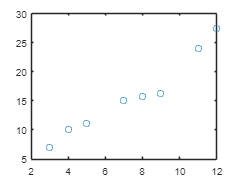


plot(x,y,'o')

**Create Z matrix**

Z=[ones(8,1) x]

Z =      1     3
     1     4
     1     5
     1     7
     1     8
     1     9
     1    11
     1    12


**Solve for unknown parameters  a  **

a = (Z' * Z) \ (Z' * y)

a =     0.3861
    2.0900


**Plot data and the best fitted curve**

xx = 3 : 0.5 :12

xx =     3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000


yy = 6.9 : 0.1 :27.5

yy =     6.9000    7.0000    7.1000    7.2000    7.3000    7.4000    7.5000    7.6000    7.7000    7.8000    7.9000    8.0000    8.1000    8.2000    8.3000    8.4000    8.5000    8.6000    8.7000    8.8000    8.9000    9.0000    9.1000    9.2000    9.3000    9.4000    9.5000    9.6000    9.7000    9.8000    9.9000   10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.9000   11.0000   11.1000   11.2000   11.3000   11.4000   11.5000   11.6000   11.7000   11.8000


plot(x,y,'o',xx,yy,'-')

Error using plot
Vectors must be the same length.

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum((y-Z*a).^2)

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y-mean(y)).^2)


**Compute  r2  (the coefficient of determination)**


r2 = 1 - Sr/St

**Compute  syx  (the standard error of the estimate)  **

syx = sqrt(Sr/(length(x)-length(a)))


**Predict the value of y for the given x**

xtest = 6
